# CLASSIFICADOR D'HISTOGRAMES

User_root      = 'C:\Users\victo\Desktop\UNI\3B\PIV\CBIR';
Data_root      = '/database/';
Input_filename = 'input.txt';
Output_filename= 'output.txt';
Num_images     = 20;
Candidates     = 10;

Input = textscan([User_root, Data_root, Input_filename],'%s');

M=2000;N=256;
matriu_candidats = zeros(M,N);

matriu_inputs = zeros(Num_images,N);

## Extruducció de característiques

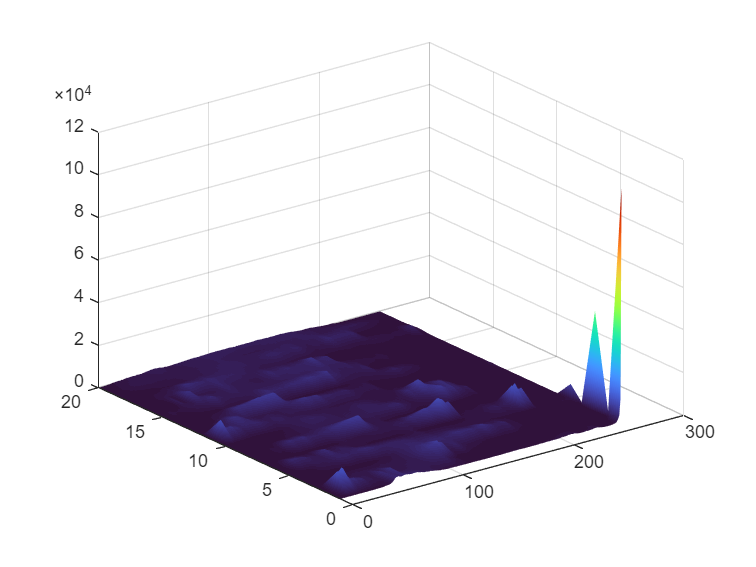

fileID = fopen("input.txt", 'r');
imageNames= textscan(fileID, '%s' );
fclose(fileID);
noms_inputs = string(imageNames{1}(1:Num_images));
for i=1:Num_images
    nom_arxiu = noms_inputs(i);
    ruta=fullfile(User_root, Data_root,nom_arxiu);
    input = imread(ruta);
    input=rgb2gray(input);
    matriu_inputs(i,:)=imhist(input).'; 
end
figure;
surf(0:255,1:size(matriu_inputs,1),matriu_inputs);
shading interp;
colormap turbo;

## Bucle per crear la matriu d'histogrames

for i=0:M-1
    nom_arxiu =  sprintf("ukbench%05d.jpg",i);
    ruta=fullfile(User_root, Data_root,nom_arxiu);
    candidat = imread(ruta);
    candidat=rgb2gray(candidat);
    matriu_candidats(i+1,:)=imhist(candidat).';
end

## Funció per veure la matriu d'histogrames en 3D

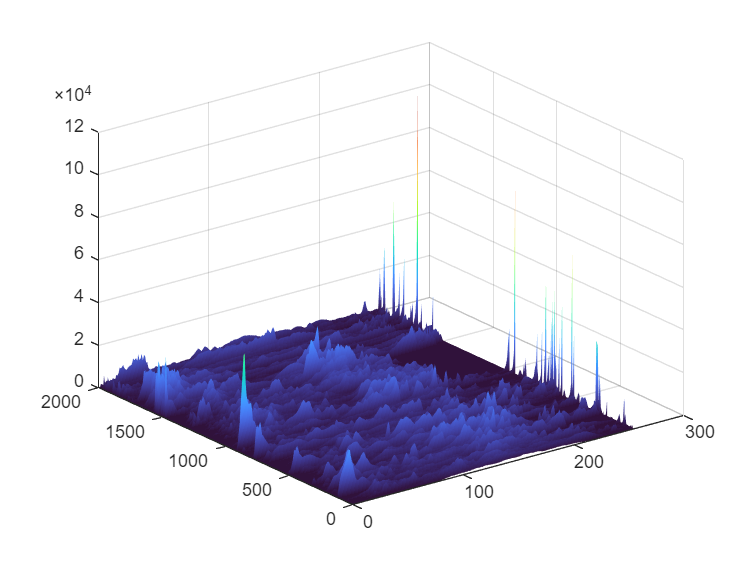

figure;
surf(0:255,1:size(matriu_candidats,1),matriu_candidats);
shading interp;
colormap turbo;

## Classificació: proposta 1.

La nostra proposta és classificar-ho a partir dels tres pics principals. Utilitzarem una funció max i ordenarem el vector histograma de gran a petit. Després buscarem els 3 pics principals a +-20 bins de distància. Un cop haguem trobat aquests pics associarem a cada histograma 3 bins i després buscarem les imatges que tenen els tres pics de bins en el punt més semblant.

% matriu_semblant_candidats = zeros(M, 3);
% for i = 1:M
%     candidat = matriu_candidats(i, :);
%     [~, locs] = findpeaks(candidat, "MinPeakDistance", 40, "SortStr", "descend");
%     k = min(3, length(locs));
%     matriu_semblant_candidats(i, 1:k) = locs(1:k);
% end
% 
% matriu_semblant_inputs = zeros(Num_images, 3);
% for i = 1:Num_images
%     input_hist = matriu_inputs(i, :);
%     [~, locs] = findpeaks(input_hist, "MinPeakDistance", 40, "SortStr", "descend");
%     k = min(3, length(locs));
%     matriu_semblant_inputs(i, 1:k) = locs(1:k);
% end
% 
% matriu_distancia_pics = zeros(Num_images, M);
% for orig = 1:Num_images
%     pics_query = matriu_semblant_inputs(orig, :);
%     for comp = 1:M
%         pics_candidat = matriu_semblant_candidats(comp, :);
%         matriu_distancia_pics(orig, comp) = sum(abs(pics_query - pics_candidat));
%     end
% end
% 
% indexs_ordenats = zeros(Num_images, M);
% for i = 1:Num_images
%     [~, idx] = sort(matriu_distancia_pics(i, :), 'ascend');
%     indexs_ordenats(i, :) = idx;
% end
% 
% millors_10_indexs = indexs_ordenats(:, 1:Candidates);

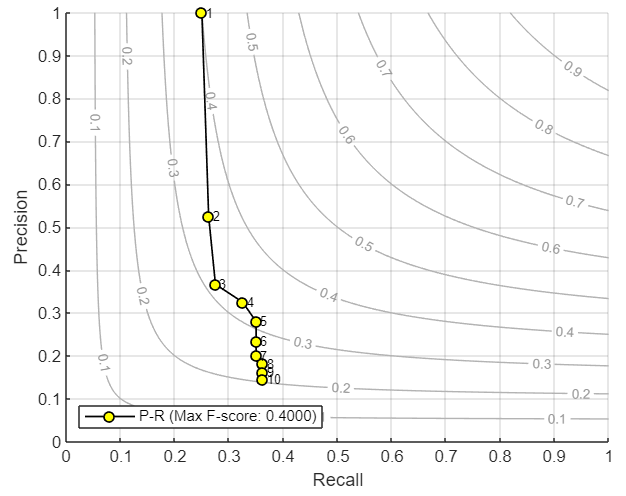

Aquesta no funcionaria massa bé perquè els pics no donen la informació que necessitem, la seva F-score és de 0.4.

## Classificació: proposta 2.

La nostra segona proposta és classificar-ho a partir de la diferència total entre els histogrames. Utilitzarem el valor absolut de la resta bin a bin entre l'histograma de la imatge d'entrada i el candidat. Després sumarem totes aquestes diferències per obtenir un únic valor de distància global. Un cop tinguem aquest sumatori per a tots els candidats, ordenarem els resultats de petit a gran i buscarem les imatges que tenen la distància més baixa, ja que seran les més semblants.

% matriu_distancia = zeros(Num_images,M);
% for orig=1:Num_images
%     for comp=1:M
%         matriu_distancia(orig,comp) =sum(abs(matriu_candidats(comp,:)-matriu_inputs(orig,:)));
%     end
% end
% 
% distancies_ordenades = zeros(Num_images, M);
% indexs_ordenats = zeros(Num_images, M);
% 
% for i = 1:Num_images
%     [valors, idx] = sort(matriu_distancia(i, :), 'ascend');
% 
%     distancies_ordenades(i, :) = valors;
%     indexs_ordenats(i, :) = idx;
% end
% 
% millors_10_indexs = indexs_ordenats(:, 1:Candidates);
% millors_10_distancies = distancies_ordenades(:, 1:Candidates);

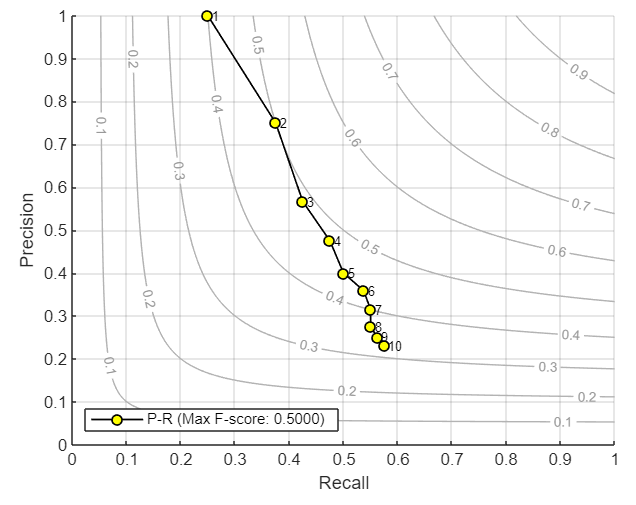

Aquesta funciona molt bé perquè l'F-score és de 0.5, però hi ha alguna proposta millor.

## Classificació: Proposta 3

La nostra tercera proposta és classificar-ho utilitzant la distància Chi-quadrat. Per calcular-la, agafarem la diferència al quadrat entre cada bin dels dos histogrames i la dividirem per la suma d'aquests dos mateixos bins. Aquesta divisió serveix per normalitzar els valors: d'aquesta manera evitem que els tons de gris dominants d'una imatge tapin la resta d'informació, donant la mateixa importància als petits detalls que a les grans àrees de fons. Un cop sumats els resultats de tots els bins per obtenir la distància total, ordenarem de petit a gran i buscarem les imatges amb el valor més proper a zero, que seran les més semblants.t

matriu_distancia = zeros(Num_images, M);

for orig = 1:Num_images
    for comp = 1:M
        h1 = matriu_inputs(orig, :);
        h2 = matriu_candidats(comp, :);
        matriu_distancia(orig, comp) = sum(((h1 - h2).^2) ./ (h1 + h2 + eps));
    end
end

distancies_ordenades = zeros(Num_images, M);
indexs_ordenats = zeros(Num_images, M);

for i = 1:Num_images
    [valors, idx] = sort(matriu_distancia(i, :), 'ascend');
    distancies_ordenades(i, :) = valors;
    indexs_ordenats(i, :) = idx;
end

millors_10_indexs = indexs_ordenats(:, 1:Candidates);

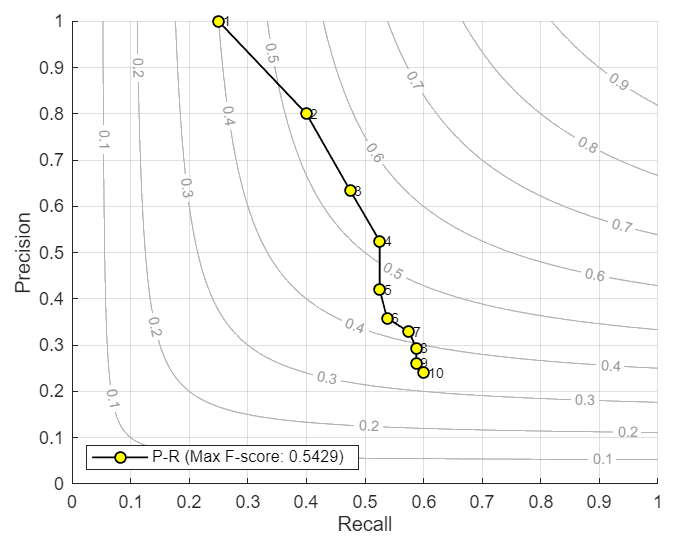

Aquesta ens ha funcionat molt bé i hem acabat assolint una F-score de 0.5571.

## Output

% Creem l'arxiu directament a la carpeta de treball actual
fileID_out = fopen('output.txt', 'w');

% Comprovació de seguretat per si l'arxiu no es pot crear
if fileID_out == -1
    error('No s''ha pogut obrir o crear l''arxiu output.txt');
end

for i = 1:Num_images
    % Convertim el nom de la imatge a 'char' per assegurar-nos que s'escriu perfectament
    nom_query = char(noms_inputs(i)); 
    fprintf(fileID_out, 'Retrieved list for query image %s\n', nom_query);
    
    for j = 1:Candidates
        % Restem 1 per passar de l'índex del MATLAB a l'ID real de la imatge
        idx_candidat = millors_10_indexs(i, j) - 1; 
        
        % Escrivim directament l'ID amb 5 dígits i extensió
        fprintf(fileID_out, 'ukbench%05d.jpg\n', idx_candidat);
    end
    
    % Salt de línia per separar les diferents imatges
    fprintf(fileID_out, '\n');
end
fclose(fileID_out);

## Mètriques

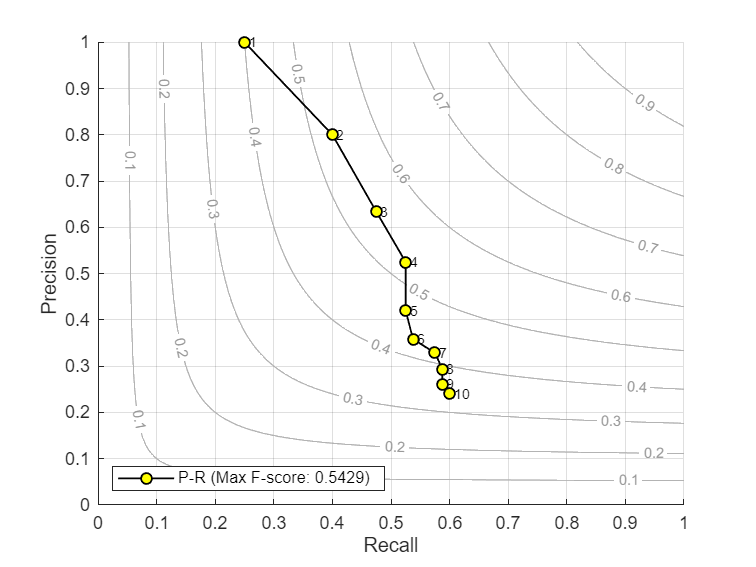

precision_pas_a_pas = zeros(Num_images, Candidates);
recall_pas_a_pas    = zeros(Num_images, Candidates);

for i = 1:Num_images
    nom_q = noms_inputs(i);
    
    % Extraiem correctament el número de la imatge amb str2double
    num_str = regexp(nom_q, '\d+', 'match');
    id_q = str2double(num_str);
    
    grup_q = floor(id_q / 4);
    encerts = 0;
    
    for j = 1:Candidates
        idx_c = millors_10_indexs(i, j) - 1;
        
        % Comprovem si el candidat pertany al mateix grup que la imatge d'entrada
        if floor(idx_c / 4) == grup_q
            encerts = encerts + 1;
        end
        
        precision_pas_a_pas(i, j) = encerts / j;
        recall_pas_a_pas(i, j) = encerts / 4; % Dividim per 4 perquè hi ha 4 imatges rellevants per grup
    end
end

% Mitjanes globals
mean_p = mean(precision_pas_a_pas, 1);
mean_r = mean(recall_pas_a_pas, 1);

% IMPORTANT: fem servir ./ perquè la divisió sigui element a element
f_scores = (2 .* (mean_p .* mean_r)) ./ (mean_p + mean_r);
f_scores(isnan(f_scores)) = 0;

max_f_score = max(f_scores);

figure;
hold on;

[R_grid, P_grid] = meshgrid(linspace(0.001, 1, 200), linspace(0.001, 1, 200));
F_grid = (2 .* P_grid .* R_grid) ./ (P_grid + R_grid);
[c, h] = contour(R_grid, P_grid, F_grid, 0.1:0.1:1.0, 'Color', [0.7 0.7 0.7], 'HandleVisibility', 'off');
clabel(c, h, 'FontSize', 8, 'Color', [0.6 0.6 0.6]);

plot(mean_r, mean_p, '-ok', 'LineWidth', 1, 'MarkerFaceColor', 'y', ...
    'DisplayName', sprintf('P-R (Max F-score: %.4f)', max_f_score));

grid on;
xticks(0:0.1:1);
yticks(0:0.1:1);
xlim([0 1]);
ylim([0 1]);
xlabel('Recall');
ylabel('Precision');

for k = 1:Candidates
    text(mean_r(k), mean_p(k), sprintf(' %d', k), 'FontSize', 8);
end

legend('Location', 'southwest');
hold off;